net = googlenet;
camera = webcam;    

다음 사용 중 오류가 발생함: webcam (line 124)
웹캠 Microsoft® LifeCam Studio(TM)에 대한 연결이 이미 존재하며 활성화되어 있습니다. 동일한 웹캠에 대해 연결을 하나 더 만들 수 없습니다.

inputSize = net.Layers(1).InputSize(1:2)

% figure
% im = snapshot(camera);
% image(im)
% im = imresize(im,inputSize);
% [label,score] = classify(net,im);
% title({char(label),num2str(max(score),2)});

% h = figure;
% 
% while ishandle(h)
%     im = snapshot(camera);
%     image(im)
%     im = imresize(im,inputSize);
%     [label,score] = classify(net,im);
%     title({char(label), num2str(max(score),2)});
%     drawnow
% end

% h = figure;
% h.Position(3) = 2*h.Position(3);
% ax1 = subplot(1,2,1);
% ax2 = subplot(1,2,2);

% im = snapshot(camera);
% image(ax1,im)
% im = imresize(im,inputSize);
% [label,score] = classify(net,im);
% title(ax1,{char(label),num2str(max(score),2)});

% [~,idx] = sort(score,'descend');
% idx = idx(5:-1:1);
% classes = net.Layers(end).Classes;
% classNamesTop = string(classes(idx));
% scoreTop = score(idx);

% barh(ax2,scoreTop)
% xlim(ax2,[0 1])
% title(ax2,'Top 5')
% xlabel(ax2,'Probability')
% yticklabels(ax2,classNamesTop)
% ax2.YAxisLocation = 'right';

% h = figure;
% h.Position(3) = 2*h.Position(3);
% ax1 = subplot(1,2,1);
% ax2 = subplot(1,2,2);
% ax2.ActivePositionProperty = 'position';

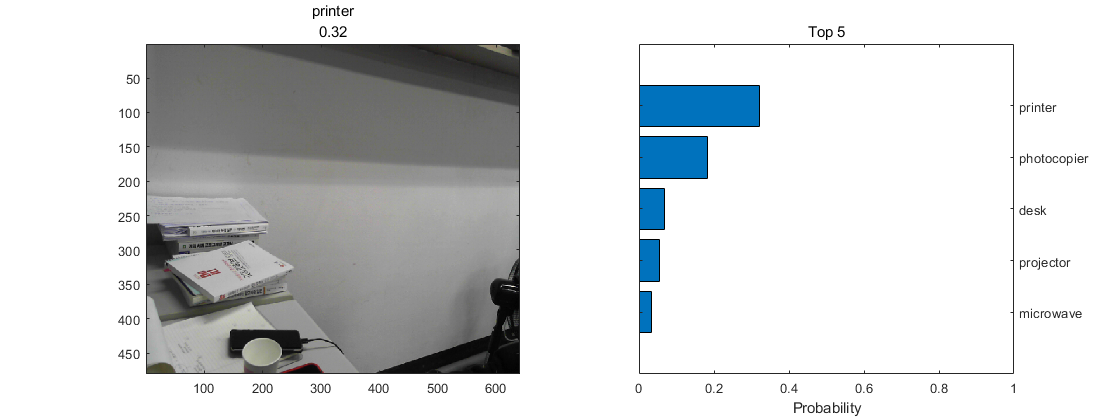

h = figure;
h.Position(3) = 2*h.Position(3);
ax1 = subplot(1,2,1);
ax2 = subplot(1,2,2);
classes = net.Layers(end).Classes;

while ishandle(h)
    % Display and classify the image
    im = snapshot(camera);
    image(ax1,im)
    im = imresize(im,inputSize);
    [label,score] = classify(net,im);
    title(ax1,{char(label),num2str(max(score),2)});

    % Select the top five predictions
    [~,idx] = sort(score,'descend');
    idx = idx(5:-1:1);
    scoreTop = score(idx);
    classNamesTop = string(classes(idx));

    % Plot the histogram
    barh(ax2,scoreTop)
    title(ax2,'Top 5')
    xlabel(ax2,'Probability')
    xlim(ax2,[0 1])
    yticklabels(ax2,classNamesTop)
    ax2.YAxisLocation = 'right';

    drawnow
end